clc; clear; close all;

%% Sensor / Target initialize

% 패시브 소나와 EKF를 이용한 방위각 기반 타겟 위치 추정 알고리즘
% 두개의 어뢰와 모선에 있는 소나 센서를 이용
% State=[x y z vx vy vz]'
% measurement=[b e]'각각 방위각, 양각 
% 필터 :  EKF
load("BadTrajec.mat");% trajectory 파일들은 따로 생성 후 관리. 이 파일 안에 trajectories.target 형태로 저장.

%% Target,Mothership and Torpedoes initialization
target=initializeTarget([90 -20],15,DOPgoodtrajectories1.target); % [azimuth elevation](deg) velocity trajectory
mship=initializeTracker(20,40000,1,target,DOPgoodtrajectories1.mship);%v,maxD,noise(deg),target,trajectory
torpedo1=initializeTracker(20,40000,1,target,DOPgoodtrajectories1.torpedo1);%v,maxD,noise(deg),target,trajectory
torpedo2=initializeTracker(20,40000,1,target,DOPgoodtrajectories1.torpedo2);%v,maxD,noise(deg),target,trajectory


%% Uncertainty Area Calculation
th=200;%threshold for combining

%% Visualization

[uncertainArea, condNum] = findUncertaintyArea(mship.sonar, torpedo1.sonar, torpedo2.sonar, th);

   200



condNum = 1.5547e+03

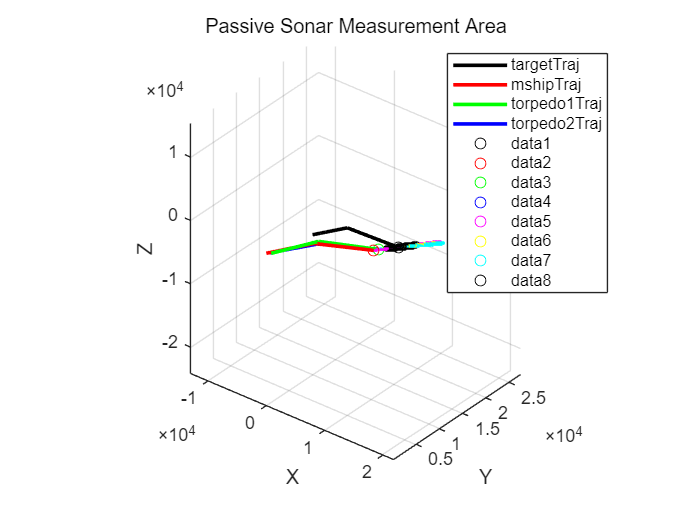

   200



condNum = 1.1367e+03

i = 1

   200



condNum = 1.3950e+03

i = 2

   200



condNum = 1.2602e+03

i = 3

   200



condNum = 1.3088e+03

i = 4

   200



condNum = 1.4579e+03

i = 5

   200



condNum = 1.2697e+03

i = 6

   200



condNum = 1.3957e+03

i = 7

   200



condNum = 1.4565e+03

i = 8

   200



condNum = 1.2128e+03

i = 9

   200



condNum = 1.1145e+03

i = 10

   200



condNum = 1.3388e+03

i = 11

   200



condNum = 1.5091e+03

i = 12

   200



condNum = 1.2952e+03

i = 13

   200



condNum = 1.1876e+03

i = 14

   200



condNum = 1.4481e+03

i = 15

   200



condNum = 1.4149e+03

i = 16

   200



condNum = 1.4414e+03

i = 17

   200



condNum = 1.5627e+03

i = 18

   200



condNum = 1.4434e+03

i = 19

   200



condNum = 1.3769e+03

i = 20

   200



condNum = 1.2826e+03

i = 21

   200



condNum = 1.2962e+03

i = 22

   200



condNum = 1.1965e+03

i = 23

   200



condNum = 1.4990e+03

i = 24

   200



condNum = 1.2076e+03

i = 25

   200



condNum = 1.2128e+03

i = 26

   200



condNum = 1.2268e+03

i = 27

   200



condNum = 1.4131e+03

i = 28

   200



condNum = 1.4460e+03

i = 29

   200



condNum = 1.3007e+03

i = 30

   200



condNum = 1.3973e+03

i = 31

   200



condNum = 1.2774e+03

i = 32

   200



condNum = 1.3906e+03

i = 33

   200



condNum = 1.2996e+03

i = 34

   200



condNum = 1.4816e+03

i = 35

   200



condNum = 1.1837e+03

i = 36

   200



condNum = 1.2283e+03

i = 37

   200



condNum = 1.2419e+03

i = 38

   200



condNum = 1.2607e+03

i = 39

   200



condNum = 1.2146e+03

i = 40

   200



condNum = 1.2983e+03

i = 41

   200



condNum = 1.4357e+03

i = 42

   200



condNum = 1.2828e+03

i = 43

   200



condNum = 1.2067e+03

i = 44

   200



condNum = 1.2981e+03

i = 45

   200



condNum = 1.4898e+03

i = 46

   200



condNum = 1.2118e+03

i = 47

   200



condNum = 1.1491e+03

i = 48

   200



condNum = 1.2262e+03

i = 49

   200



condNum = 1.3714e+03

i = 50

   200



condNum = 1.1956e+03

i = 51

   200



condNum = 1.3852e+03

i = 52

   200



condNum = 1.3720e+03

i = 53

   200



condNum = 1.3478e+03

i = 54

   200



condNum = 1.1786e+03

i = 55

   200



condNum = 1.3516e+03

i = 56

   200



condNum = 1.3739e+03

i = 57

   200



condNum = 1.1378e+03

i = 58

   200



condNum = 1.3332e+03

i = 59

   200



condNum = 1.2739e+03

i = 60

   200



condNum = 1.1960e+03

i = 61

   200



condNum = 1.3556e+03

i = 62

   200



condNum = 1.2309e+03

i = 63

   200



condNum = 1.1399e+03

i = 64

   200



condNum = 1.3650e+03

i = 65

   200



condNum = 1.1586e+03

i = 66

   200



condNum = 1.4307e+03

i = 67

   200



condNum = 1.1853e+03

i = 68

   200



condNum = 1.2403e+03

i = 69

   200



condNum = 1.3363e+03

i = 70

   200



condNum = 1.2856e+03

i = 71

   200



condNum = 1.3972e+03

i = 72

   200



condNum = 1.4662e+03

i = 73

   200



condNum = 1.2181e+03

i = 74

   200



condNum = 1.1277e+03

i = 75

   200



condNum = 1.3538e+03

i = 76

   200



condNum = 1.2058e+03

i = 77

   200



condNum = 1.3209e+03

i = 78

   200



condNum = 1.2307e+03

i = 79

   200



condNum = 1.1027e+03

i = 80

   200



condNum = 1.2080e+03

i = 81

   200



condNum = 1.1411e+03

i = 82

   200



condNum = 1.2525e+03

i = 83

   200



condNum = 1.3439e+03

i = 84

   200



condNum = 1.1616e+03

i = 85

   200



condNum = 1.1501e+03

i = 86

   200



condNum = 1.3186e+03

i = 87

   200



condNum = 1.3514e+03

i = 88

   200



condNum = 1.1918e+03

i = 89

   200



condNum = 1.2773e+03

i = 90

   200



condNum = 1.2334e+03

i = 91

   200



condNum = 1.5343e+03

i = 92

   200



condNum = 1.3353e+03

i = 93

   200



condNum = 1.1986e+03

i = 94

   200



condNum = 1.2051e+03

i = 95

   200



condNum = 1.4158e+03

i = 96

   200



condNum = 1.2175e+03

i = 97

   200



condNum = 1.5056e+03

i = 98

   200



condNum = 1.2710e+03

i = 99

   200



condNum = 1.2364e+03

i = 100

   200



condNum = 1.4025e+03

i = 101

   200



condNum = 1.1856e+03

i = 102

   200



condNum = 1.2009e+03

i = 103

   200



condNum = 1.1024e+03

i = 104

   200



condNum = 1.2118e+03

i = 105

   200



condNum = 1.3672e+03

i = 106

   200



condNum = 1.0749e+03

i = 107

   200



condNum = 1.1114e+03

i = 108

   200



condNum = 1.0589e+03

i = 109

   200



condNum = 1.1589e+03

i = 110

   200



condNum = 1.2275e+03

i = 111

   200



condNum = 1.2185e+03

i = 112

   200



condNum = 1.3220e+03

i = 113

   200



condNum = 1.2643e+03

i = 114

   200



condNum = 1.2336e+03

i = 115

   200



condNum = 1.1569e+03

i = 116

   200



condNum = 1.2333e+03

i = 117

   200



condNum = 1.1480e+03

i = 118

   200



condNum = 1.1432e+03

i = 119

   200



condNum = 1.4152e+03

i = 120

   200



condNum = 1.2705e+03

i = 121

   200



condNum = 1.1791e+03

i = 122

   200



condNum = 1.1237e+03

i = 123

   200



condNum = 1.2143e+03

i = 124

   200



condNum = 1.0223e+03

i = 125

   200



condNum = 1.1522e+03

i = 126

   200



condNum = 1.2474e+03

i = 127

   200



condNum = 1.0581e+03

i = 128

   200



condNum = 1.1440e+03

i = 129

   200



condNum = 1.1193e+03

i = 130

   200



condNum = 1.1304e+03

i = 131

   200



condNum = 1.2998e+03

i = 132

   200



condNum = 1.1013e+03

i = 133

   200



condNum = 1.0734e+03

i = 134

   200



condNum = 1.3190e+03

i = 135

   200



condNum = 1.1349e+03

i = 136

   200



condNum = 1.1756e+03

i = 137

   200



condNum = 991.5497

i = 138

   200



condNum = 1.0921e+03

i = 139

   200



condNum = 1.1546e+03

i = 140

   200



condNum = 1.3332e+03

i = 141

   200



condNum = 1.1175e+03

i = 142

   200



condNum = 1.1679e+03

i = 143

   200



condNum = 1.0725e+03

i = 144

   200



condNum = 1.4222e+03

i = 145

   200



condNum = 1.0380e+03

i = 146

   200



condNum = 1.0304e+03

i = 147

   200



condNum = 1.0305e+03

i = 148

   200



condNum = 1.0916e+03

i = 149

   200



condNum = 894.1644

i = 150

   200



condNum = 1.0660e+03

i = 151

   200



condNum = 1.1369e+03

i = 152

   200



condNum = 1.2948e+03

i = 153

   200



condNum = 1.1464e+03

i = 154

   200



condNum = 1.1554e+03

i = 155

   200



condNum = 1.1421e+03

i = 156

   200



condNum = 1.1811e+03

i = 157

   200



condNum = 1.1685e+03

i = 158

   200



condNum = 1.2735e+03

i = 159

   200



condNum = 1.0535e+03

i = 160

   200



condNum = 1.1585e+03

i = 161

   200



condNum = 963.0017

i = 162

   200



condNum = 1.0878e+03

i = 163

   200



condNum = 1.0987e+03

i = 164

   200



condNum = 1.0964e+03

i = 165

   200



condNum = 1.2349e+03

i = 166

   200



condNum = 1.1811e+03

i = 167

   200



condNum = 1.0236e+03

i = 168

   200



condNum = 1.1726e+03

i = 169

   200



condNum = 1.1693e+03

i = 170

   200



condNum = 1.0740e+03

i = 171

   200



condNum = 1.0567e+03

i = 172

   200



condNum = 1.0269e+03

i = 173

   200



condNum = 1.1044e+03

i = 174

   200



condNum = 1.0493e+03

i = 175

   200



condNum = 1.0870e+03

i = 176

   200



condNum = 1.1045e+03

i = 177

   200



condNum = 1.1063e+03

i = 178

   200



condNum = 1.0246e+03

i = 179

   200



condNum = 1.0075e+03

i = 180

   200



condNum = 958.2450

i = 181

   200



condNum = 1.0703e+03

i = 182

   200



condNum = 1.0286e+03

i = 183

   200



condNum = 1.0352e+03

i = 184

   200



condNum = 1.1828e+03

i = 185

   200



condNum = 900.9171

i = 186

   200



condNum = 975.5814

i = 187

   200



condNum = 1.2138e+03

i = 188

   200



condNum = 992.4974

i = 189

   200



condNum = 1.0389e+03

i = 190

   200



condNum = 1.0746e+03

i = 191

   200



condNum = 1.0556e+03

i = 192

   200



condNum = 1.1600e+03

i = 193

   200



condNum = 990.3298

i = 194

   200



condNum = 1.0166e+03

i = 195

   200



condNum = 1.0312e+03

i = 196

   200



condNum = 1.2820e+03

i = 197

   200



condNum = 1.0401e+03

i = 198

   200



condNum = 1.1577e+03

i = 199

   200



condNum = 1.0064e+03

i = 200

   200



condNum = 875.8777

i = 201

   200



condNum = 1.1321e+03

i = 202

   200



condNum = 1.0846e+03

i = 203

   200



condNum = 1.0168e+03

i = 204

   200



condNum = 1.0904e+03

i = 205

   200



condNum = 978.9779

i = 206

   200



condNum = 980.2275

i = 207

   200



condNum = 1.1513e+03

i = 208

   200



condNum = 917.4516

i = 209

   200



condNum = 1.0046e+03

i = 210

   200



condNum = 991.4200

i = 211

   200



condNum = 903.7769

i = 212

   200



condNum = 1.0630e+03

i = 213

   200



condNum = 1.1542e+03

i = 214

   200



condNum = 1.2876e+03

i = 215

   200



condNum = 1.0740e+03

i = 216

   200



condNum = 1.1015e+03

i = 217

   200



condNum = 1.0606e+03

i = 218

   200



condNum = 1.0329e+03

i = 219

   200



condNum = 994.7129

i = 220

   200



condNum = 940.6535

i = 221

   200



condNum = 879.9043

i = 222

   200



condNum = 1.0113e+03

i = 223

   200



condNum = 1.0502e+03

i = 224

   200



condNum = 1.0727e+03

i = 225

   200



condNum = 930.6354

i = 226

   200



condNum = 978.5763

i = 227

   200



condNum = 1.0342e+03

i = 228

   200



condNum = 921.6206

i = 229

   200



condNum = 1.0233e+03

i = 230

   200



condNum = 1.0561e+03

i = 231

   200



condNum = 979.6138

i = 232

   200



condNum = 1.0120e+03

i = 233

   200



condNum = 1.1144e+03

i = 234

   200



condNum = 936.9503

i = 235

   200



condNum = 1.0584e+03

i = 236

   200



condNum = 1.0222e+03

i = 237

   200



condNum = 1.2654e+03

i = 238

   200



condNum = 836.7171

i = 239

   200



condNum = 859.6069

i = 240

   200



condNum = 883.7833

i = 241

   200



condNum = 956.0050

i = 242

   200



condNum = 911.5036

i = 243

   200



condNum = 1.0296e+03

i = 244

   200



condNum = 898.0920

i = 245

   200



condNum = 1.0702e+03

i = 246

   200



condNum = 900.8282

i = 247

   200



condNum = 908.7847

i = 248

   200



condNum = 1.0212e+03

i = 249

   200



condNum = 864.1466

i = 250

   200



condNum = 861.4992

i = 251

   200



condNum = 1.0801e+03

i = 252

   200



condNum = 892.1632

i = 253

   200



condNum = 982.6008

i = 254

   200



condNum = 971.1200

i = 255

   200



condNum = 881.0483

i = 256

   200



condNum = 1.0201e+03

i = 257

   200



condNum = 933.1978

i = 258

   200



condNum = 932.2009

i = 259

   200



condNum = 1.0355e+03

i = 260

   200



condNum = 961.7323

i = 261

   200



condNum = 969.4249

i = 262

   200



condNum = 917.0369

i = 263

   200



condNum = 912.1272

i = 264

   200



condNum = 1.0084e+03

i = 265

   200



condNum = 1.0585e+03

i = 266

   200



condNum = 943.8076

i = 267

   200



condNum = 947.7197

i = 268

   200



condNum = 855.0568

i = 269

   200



condNum = 989.8158

i = 270

   200



condNum = 925.0099

i = 271

   200



condNum = 1.0497e+03

i = 272

   200



condNum = 968.9381

i = 273

   200



condNum = 804.6955

i = 274

   200



condNum = 973.2734

i = 275

   200



condNum = 963.5147

i = 276

   200



condNum = 890.7214

i = 277

   200



condNum = 918.2038

i = 278

   200



condNum = 885.4026

i = 279

   200



condNum = 959.5758

i = 280

   200



condNum = 855.7225

i = 281

   200



condNum = 937.0862

i = 282

   200



condNum = 866.3190

i = 283

   200



condNum = 968.1102

i = 284

   200



condNum = 972.0569

i = 285

   200



condNum = 999.4869

i = 286

   200



condNum = 898.6757

i = 287

   200



condNum = 861.4421

i = 288

   200



condNum = 938.2369

i = 289

   200



condNum = 886.2582

i = 290

   200



condNum = 938.2617

i = 291

   200



condNum = 896.0657

i = 292

   200



condNum = 929.5459

i = 293

   200



condNum = 869.4448

i = 294

   200



condNum = 823.9514

i = 295

   200



condNum = 773.4236

i = 296

   200



condNum = 869.1035

i = 297

   200



condNum = 768.8348

i = 298

   200



condNum = 940.1916

i = 299

   200



condNum = 910.6427

i = 300

   200



condNum = 822.8219

i = 301

   200



condNum = 1.0152e+03

i = 302

   200



condNum = 789.1750

i = 303

   200



condNum = 982.5808

i = 304

   200



condNum = 747.5868

i = 305

   200



condNum = 1.0065e+03

i = 306

   200



condNum = 861.7869

i = 307

   200



condNum = 892.3437

i = 308

   200



condNum = 900.5360

i = 309

   200



condNum = 866.4573

i = 310

   200



condNum = 897.5825

i = 311

   200



condNum = 821.9906

i = 312

   200



condNum = 926.1320

i = 313

   200



condNum = 777.8067

i = 314

   200



condNum = 850.0820

i = 315

   200



condNum = 1.0486e+03

i = 316

   200



condNum = 941.7195

i = 317

   200



condNum = 745.5357

i = 318

   200



condNum = 972.9675

i = 319

   200



condNum = 863.2842

i = 320

   200



condNum = 798.4421

i = 321

   200



condNum = 943.6118

i = 322

   200



condNum = 849.8473

i = 323

   200



condNum = 785.6435

i = 324

   200



condNum = 769.7492

i = 325

   200



condNum = 899.9928

i = 326

   200



condNum = 909.3506

i = 327

   200



condNum = 826.1128

i = 328

   200



condNum = 1.0052e+03

i = 329

   200



condNum = 710.5053

i = 330

   200



condNum = 961.7806

i = 331

   200



condNum = 861.6253

i = 332

   200



condNum = 923.2701

i = 333

   200



condNum = 795.6541

i = 334

   200



condNum = 798.7855

i = 335

   200



condNum = 870.2794

i = 336

   200



condNum = 801.3657

i = 337

   200



condNum = 809.4532

i = 338

   200



condNum = 813.1324

i = 339

   200



condNum = 727.0088

i = 340

   200



condNum = 725.5242

i = 341

   200



condNum = 862.8907

i = 342

   200



condNum = 758.2856

i = 343

   200



condNum = 937.8063

i = 344

   200



condNum = 854.0381

i = 345

   200



condNum = 866.8534

i = 346

   200



condNum = 951.9045

i = 347

   200



condNum = 800.7315

i = 348

   200



condNum = 766.1524

i = 349

   200



condNum = 745.7312

i = 350

   200



condNum = 774.0904

i = 351

   200



condNum = 860.5810

i = 352

   200



condNum = 829.7714

i = 353

   200



condNum = 860.3149

i = 354

   200



condNum = 937.8406

i = 355

   200



condNum = 842.6126

i = 356

   200



condNum = 764.6979

i = 357

   200



condNum = 758.6425

i = 358

   200



condNum = 793.9920

i = 359

   200



condNum = 761.3645

i = 360

   200



condNum = 1.0361e+03

i = 361

   200



condNum = 799.6680

i = 362

   200



condNum = 861.5438

i = 363

   200



condNum = 800.8220

i = 364

   200



condNum = 807.7951

i = 365

   200



condNum = 773.5521

i = 366

   200



condNum = 777.9347

i = 367

   200



condNum = 747.1425

i = 368

   200



condNum = 752.4183

i = 369

   200



condNum = 737.4799

i = 370

   200



condNum = 790.8745

i = 371

   200



condNum = 840.5552

i = 372

   200



condNum = 949.8092

i = 373

   200



condNum = 748.4892

i = 374

   200



condNum = 802.2695

i = 375

   200



condNum = 680.8341

i = 376

   200



condNum = 856.3157

i = 377

   200



condNum = 847.9788

i = 378

   200



condNum = 722.2552

i = 379

   200



condNum = 736.6640

i = 380

   200



condNum = 878.5893

i = 381

   200



condNum = 771.6023

i = 382

   200



condNum = 917.7700

i = 383

   200



condNum = 845.4544

i = 384

   200



condNum = 889.1405

i = 385

   200



condNum = 756.4966

i = 386

   200



condNum = 702.1377

i = 387

   200



condNum = 719.0493

i = 388

   200



condNum = 808.9550

i = 389

   200



condNum = 808.8575

i = 390

   200



condNum = 889.9297

i = 391

   200



condNum = 710.6549

i = 392

   200



condNum = 814.9967

i = 393

   200



condNum = 902.4622

i = 394

   200



condNum = 822.8793

i = 395

   200



condNum = 800.2715

i = 396

   200



condNum = 816.3239

i = 397

   200



condNum = 745.4755

i = 398

   200



condNum = 795.8456

i = 399

   200



condNum = 794.5863

i = 400

   200



condNum = 837.6877

i = 401

   200



condNum = 816.8862

i = 402

   200



condNum = 772.6503

i = 403

   200



condNum = 703.7689

i = 404

   200



condNum = 807.5368

i = 405

   200



condNum = 749.0882

i = 406

   200



condNum = 684.1681

i = 407

   200



condNum = 849.7332

i = 408

   200



condNum = 766.3448

i = 409

   200



condNum = 731.2992

i = 410

   200



condNum = 773.6396

i = 411

   200



condNum = 799.2693

i = 412

   200



condNum = 687.1420

i = 413

   200



condNum = 739.0613

i = 414

   200



condNum = 743.9222

i = 415

   200



condNum = 751.9369

i = 416

   200



condNum = 899.8584

i = 417

   200



condNum = 783.1299

i = 418

   200



condNum = 899.8892

i = 419

   200



condNum = 741.5117

i = 420

   200



condNum = 763.9958

i = 421

   200



condNum = 910.9012

i = 422

   200



condNum = 926.7214

i = 423

   200



condNum = 772.2873

i = 424

   200



condNum = 785.0361

i = 425

   200



condNum = 836.5599

i = 426

   200



condNum = 805.1670

i = 427

   200



condNum = 815.2918

i = 428

   200



condNum = 812.7342

i = 429

   200



condNum = 751.0032

i = 430

   200



condNum = 805.3984

i = 431

   200



condNum = 738.0205

i = 432

   200



condNum = 832.4155

i = 433

   200



condNum = 718.7015

i = 434

   200



condNum = 699.3704

i = 435

   200



condNum = 746.4324

i = 436

   200



condNum = 688.2533

i = 437

   200



condNum = 694.8040

i = 438

   200



condNum = 740.0781

i = 439

   200



condNum = 727.4573

i = 440

   200



condNum = 813.0705

i = 441

   200



condNum = 753.9737

i = 442

   200



condNum = 840.3814

i = 443

   200



condNum = 785.4857

i = 444

   200



condNum = 682.7565

i = 445

   200



condNum = 683.6629

i = 446

   200



condNum = 868.5755

i = 447

   200



condNum = 820.6524

i = 448

   200



condNum = 788.4784

i = 449

   200



condNum = 792.1763

i = 450

   200



condNum = 720.8981

i = 451

   200



condNum = 717.5028

i = 452

   200



condNum = 728.5418

i = 453

   200



condNum = 759.3615

i = 454

   200



condNum = 800.6209

i = 455

   200



condNum = 792.8058

i = 456

   200



condNum = 670.0444

i = 457

   200



condNum = 668.2074

i = 458

   200



condNum = 740.5822

i = 459

   200



condNum = 820.0514

i = 460

   200



condNum = 647.0160

i = 461

   200



condNum = 744.2397

i = 462

   200



condNum = 923.7786

i = 463

   200



condNum = 840.3492

i = 464

   200



condNum = 767.0235

i = 465

   200



condNum = 751.7204

i = 466

   200



condNum = 686.6305

i = 467

   200



condNum = 590.7568

i = 468

   200



condNum = 838.8114

i = 469

   200



condNum = 774.5614

i = 470

   200



condNum = 629.3650

i = 471

   200



condNum = 729.3985

i = 472

   200



condNum = 820.6320

i = 473

   200



condNum = 710.8337

i = 474

   200



condNum = 720.8657

i = 475

   200



condNum = 768.3064

i = 476

   200



condNum = 823.5901

i = 477

   200



condNum = 681.2353

i = 478

   200



condNum = 813.8326

i = 479

   200



condNum = 782.5916

i = 480

   200



condNum = 707.8500

i = 481

   200



condNum = 689.4431

i = 482

   200



condNum = 735.5348

i = 483

   200



condNum = 718.6156

i = 484

   200



condNum = 772.1479

i = 485

   200



condNum = 657.2595

i = 486

   200



condNum = 689.1257

i = 487

   200



condNum = 668.7441

i = 488

   200



condNum = 734.9247

i = 489

   200



condNum = 754.4693

i = 490

   200



condNum = 780.1553

i = 491

   200



condNum = 657.5409

i = 492

   200



condNum = 757.8563

i = 493

   200



condNum = 805.9260

i = 494

   200



condNum = 862.5536

i = 495

   200



condNum = 685.6175

i = 496

   200



condNum = 616.4374

i = 497

   200



condNum = 649.9489

i = 498

   200



condNum = 670.6453

i = 499

   200



condNum = 657.4589

i = 500

   200



condNum = 762.8277

i = 501

   200



condNum = 738.3974

i = 502

   200



condNum = 703.3692

i = 503

   200



condNum = 774.6747

i = 504

   200



condNum = 643.3393

i = 505

   200



condNum = 733.8111

i = 506

   200



condNum = 642.9496

i = 507

   200



condNum = 796.9600

i = 508

   200



condNum = 720.5866

i = 509

   200



condNum = 689.6431

i = 510

   200



condNum = 726.7768

i = 511

   200



condNum = 731.2738

i = 512

   200



condNum = 678.5441

i = 513

   200



condNum = 788.9352

i = 514

   200



condNum = 725.4074

i = 515

   200



condNum = 771.0132

i = 516

   200



condNum = 807.8169

i = 517

   200



condNum = 835.2906

i = 518

   200



condNum = 783.1936

i = 519

   200



condNum = 756.2603

i = 520

   200



condNum = 755.6108

i = 521

   200



condNum = 836.7202

i = 522

   200



condNum = 693.9660

i = 523

   200



condNum = 825.2391

i = 524

   200



condNum = 808.5163

i = 525

   200



condNum = 778.1364

i = 526

   200



condNum = 696.3259

i = 527

   200



condNum = 874.9709

i = 528

   200



condNum = 810.7840

i = 529

   200



condNum = 797.0083

i = 530

   200



condNum = 787.5022

i = 531

   200



condNum = 787.2598

i = 532

   200



condNum = 866.1719

i = 533

   200



condNum = 772.0127

i = 534

   200



condNum = 939.0894

i = 535

   200



condNum = 872.7266

i = 536

   200



condNum = 877.2987

i = 537

   200



condNum = 794.4686

i = 538

   200



condNum = 827.2229

i = 539

   200



condNum = 948.1555

i = 540

   200



condNum = 787.5569

i = 541

   200



condNum = 732.4622

i = 542

   200



condNum = 904.2478

i = 543

   200



condNum = 773.3382

i = 544

   200



condNum = 795.8822

i = 545

   200



condNum = 705.4783

i = 546

   200



condNum = 789.9970

i = 547

   200



condNum = 792.1207

i = 548

   200



condNum = 918.9130

i = 549

   200



condNum = 877.7189

i = 550

   200



condNum = 880.7919

i = 551

   200



condNum = 731.8800

i = 552

   200



condNum = 892.0994

i = 553

   200



condNum = 813.6495

i = 554

   200



condNum = 1.0202e+03

i = 555

   200



condNum = 998.8401

i = 556

   200



condNum = 915.5159

i = 557

   200



condNum = 1.0298e+03

i = 558

   200



condNum = 850.3014

i = 559

   200



condNum = 766.3056

i = 560

   200



condNum = 786.1245

i = 561

   200



condNum = 792.4383

i = 562

   200



condNum = 1.0397e+03

i = 563

   200



condNum = 825.5575

i = 564

   200



condNum = 975.6918

i = 565

   200



condNum = 853.4816

i = 566

   200



condNum = 793.9818

i = 567

   200



condNum = 854.7557

i = 568

   200



condNum = 943.4754

i = 569

   200



condNum = 978.5912

i = 570

   200



condNum = 970.7830

i = 571

   200



condNum = 895.7433

i = 572

   200



condNum = 933.0080

i = 573

   200



condNum = 902.4996

i = 574

   200



condNum = 985.3943

i = 575

   200



condNum = 941.5856

i = 576

   200



condNum = 893.2376

i = 577

   200



condNum = 883.1312

i = 578

   200



condNum = 860.7892

i = 579

   200



condNum = 820.4687

i = 580

   200



condNum = 865.0353

i = 581

   200



condNum = 908.5410

i = 582

   200



condNum = 1.0440e+03

i = 583

   200



condNum = 1.0402e+03

i = 584

   200



condNum = 965.2496

i = 585

   200



condNum = 958.3536

i = 586

   200



condNum = 961.4724

i = 587

   200



condNum = 992.9426

i = 588

   200



condNum = 899.3015

i = 589

   200



condNum = 905.8677

i = 590

   200



condNum = 950.6549

i = 591

   200



condNum = 1.0194e+03

i = 592

   200



condNum = 912.8378

i = 593

   200



condNum = 911.3513

i = 594

   200



condNum = 1.0314e+03

i = 595

   200



condNum = 975.7266

i = 596

   200



condNum = 1.0073e+03

i = 597

   200



condNum = 985.0938

i = 598

   200



condNum = 1.0368e+03

i = 599

   200



condNum = 1.2021e+03

i = 600

   200



condNum = 979.1628

i = 601

   200



condNum = 871.3333

i = 602

   200



condNum = 1.0162e+03

i = 603

   200



condNum = 1.0120e+03

i = 604

   200



condNum = 979.5026

i = 605

   200



condNum = 930.1927

i = 606

   200



condNum = 1.0093e+03

i = 607

   200



condNum = 987.7234

i = 608

   200



condNum = 1.0321e+03

i = 609

   200



condNum = 1.0367e+03

i = 610

   200



condNum = 1.0919e+03

i = 611

   200



condNum = 952.1229

i = 612

   200



condNum = 1.1532e+03

i = 613

   200



condNum = 928.4651

i = 614

   200



condNum = 1.1158e+03

i = 615

   200



condNum = 1.2191e+03

i = 616

   200



condNum = 1.1319e+03

i = 617

   200



condNum = 1.0645e+03

i = 618

   200



condNum = 1.0975e+03

i = 619

   200



condNum = 1.0362e+03

i = 620

   200



condNum = 1.0962e+03

i = 621

   200



condNum = 1.0991e+03

i = 622

   200



condNum = 1.0471e+03

i = 623

   200



condNum = 984.5124

i = 624

   200



condNum = 1.2226e+03

i = 625

   200



condNum = 1.0921e+03

i = 626

   200



condNum = 914.3372

i = 627

   200



condNum = 1.0557e+03

i = 628

   200



condNum = 1.2147e+03

i = 629

   200



condNum = 1.0574e+03

i = 630

   200



condNum = 1.0226e+03

i = 631

   200



condNum = 1.0460e+03

i = 632

   200



condNum = 1.0076e+03

i = 633

   200



condNum = 1.1096e+03

i = 634

   200



condNum = 1.0354e+03

i = 635

   200



condNum = 1.1633e+03

i = 636

   200



condNum = 1.1991e+03

i = 637

   200



condNum = 1.1036e+03

i = 638

   200



condNum = 1.0560e+03

i = 639

   200



condNum = 1.0309e+03

i = 640

   200



condNum = 1.0158e+03

i = 641

   200



condNum = 981.3184

i = 642

   200



condNum = 1.0952e+03

i = 643

   200



condNum = 1.0592e+03

i = 644

   200



condNum = 1.3510e+03

i = 645

   200



condNum = 1.0638e+03

i = 646

   200



condNum = 1.0029e+03

i = 647

   200



condNum = 1.1812e+03

i = 648

   200



condNum = 1.0137e+03

i = 649

   200



condNum = 1.0391e+03

i = 650

   200



condNum = 1.1576e+03

i = 651

   200



condNum = 1.2760e+03

i = 652

   200



condNum = 1.1329e+03

i = 653

   200



condNum = 1.1269e+03

i = 654

   200



condNum = 1.1796e+03

i = 655

   200



condNum = 1.1731e+03

i = 656

   200



condNum = 1.2138e+03

i = 657

   200



condNum = 1.2757e+03

i = 658

   200



condNum = 1.0671e+03

i = 659

   200



condNum = 1.2338e+03

i = 660

   200



condNum = 1.1447e+03

i = 661

   200



condNum = 1.0924e+03

i = 662

   200



condNum = 1.2180e+03

i = 663

   200



condNum = 1.3044e+03

i = 664

   200



condNum = 1.2482e+03

i = 665

   200



condNum = 1.2996e+03


figure; hold on;
plot3(target.traj(:,1), target.traj(:,2), target.traj(:,3), 'k-', 'LineWidth', 2);
plot3(mship.traj(:,1), mship.traj(:,2), mship.traj(:,3), 'r-', 'LineWidth', 2);
plot3(torpedo1.traj(:,1), torpedo1.traj(:,2), torpedo1.traj(:,3), 'g-', 'LineWidth', 2);
plot3(torpedo2.traj(:,1), torpedo2.traj(:,2), torpedo2.traj(:,3), 'b-', 'LineWidth', 2);

plot3(target.Pos(1),target.Pos(2),target.Pos(3),'ko', 'Tag', 'SonarPoints');
plot3(mship.Pos(1),mship.Pos(2),mship.Pos(3),'ro', 'Tag', 'SonarPoints');
plot3(torpedo1.Pos(1),torpedo1.Pos(2),torpedo1.Pos(3),'go', 'Tag', 'SonarPoints');
plot3(torpedo2.Pos(1),torpedo2.Pos(2),torpedo2.Pos(3),'bo', 'Tag', 'SonarPoints');

scatter3(mship.sonar.points(:,1), mship.sonar.points(:,2), mship.sonar.points(:,3),1,'m', 'Tag', 'SonarPoints');

scatter3(torpedo1.sonar.points(:,1), torpedo1.sonar.points(:,2), torpedo1.sonar.points(:,3),1,'y', 'Tag', 'SonarPoints');

scatter3(torpedo2.sonar.points(:,1), torpedo2.sonar.points(:,2), torpedo2.sonar.points(:,3),1,'c', 'Tag', 'SonarPoints');
scatter3(uncertainArea(:,1), uncertainArea(:,2), uncertainArea(:,3),10,'ko', 'Tag', 'SonarPoints');

title('Passive Sonar Measurement Area');
xlabel('X'); ylabel('Y'); zlabel('Z');
legend('targetTraj','mshipTraj','torpedo1Traj','torpedo2Traj','targetPos','mshipPos','torpedo1Pos','torpedo2Pos','mshipSonar','torpedo1Sonar','torpedo2Sonar','uncertaintyArea');
axis equal;

% xlim([-10000 15000]);
% ylim([0 25000]);
% zlim([-12500 12500]);

grid on;
view([40 -50 40]);

%% Simulation
condition=zeros(length(target.traj),1);
for i=1:1:length(target.traj)

    %sonar sensor measuring
    mship.sonar = updateSensor(mship.sonar.maxD, 1, mship.State(1:3), mship.heading);
    torpedo1.sonar = updateSensor(torpedo1.sonar.maxD, 1, torpedo1.State(1:3), torpedo1.heading);
    torpedo2.sonar = updateSensor(torpedo2.sonar.maxD, 1, torpedo2.State(1:3), torpedo2.heading);

    %extract uncertainarea of sonar sensors
    [uncertainArea,condNum] = findUncertaintyArea(mship.sonar, torpedo1.sonar, torpedo2.sonar, th);
    condition(i)=condNum;

    i%counting progress

   
    % drawnow;
    delete(findobj(gca, 'Tag', 'SonarPoints'));

    plot3(target.Pos(1),target.Pos(2),target.Pos(3),'ko', 'Tag', 'SonarPoints');
    plot3(mship.Pos(1),mship.Pos(2),mship.Pos(3),'ro', 'Tag', 'SonarPoints');
    plot3(torpedo1.Pos(1),torpedo1.Pos(2),torpedo1.Pos(3),'go', 'Tag', 'SonarPoints');
    plot3(torpedo2.Pos(1),torpedo2.Pos(2),torpedo2.Pos(3),'bo', 'Tag', 'SonarPoints');

    scatter3(mship.sonar.points(:,1), mship.sonar.points(:,2), mship.sonar.points(:,3), 1, 'm', 'Tag', 'SonarPoints');
    scatter3(torpedo1.sonar.points(:,1), torpedo1.sonar.points(:,2), torpedo1.sonar.points(:,3), 1, 'y', 'Tag', 'SonarPoints');
    scatter3(torpedo2.sonar.points(:,1), torpedo2.sonar.points(:,2), torpedo2.sonar.points(:,3), 1, 'c', 'Tag', 'SonarPoints');
    scatter3(uncertainArea(:,1), uncertainArea(:,2), uncertainArea(:,3), 10, 'ko', 'Tag', 'SonarPoints');

    drawnow;
     %model state update
    target=updateTarget(target);
    mship=updateTracker(mship,target);
    torpedo1=updateTracker(torpedo1,target);
    torpedo2=updateTracker(torpedo2,target);
end

%% downscaling conditionNumber

%% Visualization
figure; hold on;
plot([1:length(condition)],condition)
title('Condition Number');
xlabel('Time'); ylabel('ConditionNumber');
legend('CondNum');
grid on;
hold off;


%% Functions

% Update Sensor Function
function sonar = updateSensor(maxDistance, noise, position, heading)
    sonar.maxD = maxDistance; % 최대 측정 거리
    sonar.noise = deg2rad(noise); % 각 센서의 measurement Noise (angle)
    sonar.maxR = tan(sonar.noise) * sonar.maxD; % noise 기반 원뿔 반지름 생성
    sonar.numPoints = 1000; % 포인트 수

    sonar.P = position'; % 센서 위치
    sonar.D = [cos(heading(2)) * cos(heading(1)), ...
               cos(heading(2)) * sin(heading(1)), ...
               sin(heading(2))]; % 헤딩 방향은 방위각과 양각 기반으로 생성

    % 랜덤 포인트 생성
    theta1 = 2 * pi * rand(sonar.numPoints, 1);
    z1 = sonar.maxD * rand(sonar.numPoints, 1);
    r1 = sqrt(rand(sonar.numPoints, 1)) .* (z1 / sonar.maxD) * sonar.maxR;
    x1 = r1 .* cos(theta1);
    y1 = r1 .* sin(theta1);

    % 좌표 변환 (회전 및 병진 변환 적용)
    sonar.points = [x1, y1, z1];
    zAxis = [0, 0, 1];
    v = cross(zAxis, sonar.D);
    s = norm(v);
    c = dot(zAxis, sonar.D);
    vx = [0, -v(3), v(2); v(3), 0, -v(1); -v(2), v(1), 0];
    R = eye(3) + vx + vx^2 * ((1 - c) / s^2);
    sonar.points = (R * sonar.points')' + sonar.P;
end

% Find Uncertainty Area Function
function [uncertainty, condNum] = findUncertaintyArea(sensor1, sensor2, sensor3, th)
    % sensor1, sensor2, sensor3: 구조체, 각각 points (Point Cloud), P (위치), D (방향) 등 포함
    % th: 거리 임계값 (겹치는 영역 기준)
    % uncertainty: 세 UUV의 겹치는 영역 (공통 포인트)
    checkpoint_a=length(sensor1.points)/2;
    checkpoint_b=checkpoint_a+1;
    
    th=th;
    disp(th)
    % Step 1: Sensor 1과 Sensor 2 간의 겹치는 영역 계산
    distances12 = pdist2(sensor1.points, sensor2.points);
    [UUV1_matchIdx_12, ~] = find(distances12 < th);
    overlap12 = sensor1.points(UUV1_matchIdx_12, :);

    % Step 2: Sensor 3과 overlap12의 겹치는 영역 계산
    distances123 = pdist2(overlap12, sensor3.points);
    [overlap12_matchIdx, ~] = find(distances123 < th);
    uncertainty = overlap12(overlap12_matchIdx, :);

    % 공분산 행렬 계산
    covMat = cov(uncertainty);
    % 
    % % 고유 값 및 고유 벡터 계산
    % [eigenVect, eigenVal] = eig(covMat);

    % 컨디션 넘버 계산
    condNum = cond(covMat);
    if condNum==inf
        condNum=100;
    end
    condNum
end

%모델 초기화
function target=initializeTarget(heading,v,trajectory)
    target.vel = v; % 속력
    target.heading = [deg2rad(heading(1)) deg2rad(heading(2))]; % 헤딩각
    target.Pos = trajectory(1,:);
    target.PosIdx=1;
    target.State = [target.Pos, ...
    target.vel * cos(target.heading(2)) * cos(target.heading(1)), ...
    target.vel * cos(target.heading(2)) * sin(target.heading(1)), ...
    target.vel * sin(target.heading(2))]'; % 상태 변수
    target.traj=trajectory;
end

function tracker=initializeTracker(v,maxD,noise,target,trajectory)
    tracker.vel = v;
    tracker.Pos = trajectory(1,:);
    tracker.PosIdx=1;
    tracker.heading = [atan2(target.Pos(2) - tracker.Pos(2), target.Pos(1) - tracker.Pos(1)), ...
        atan2(target.Pos(3) - tracker.Pos(3), norm(target.Pos(1:2) - tracker.Pos(1:2)))];
    tracker.State = [tracker.Pos, ...
        tracker.vel * cos(tracker.heading(2)) * cos(tracker.heading(1)), ...
        tracker.vel * cos(tracker.heading(2)) * sin(tracker.heading(1)), ...
        tracker.vel * sin(tracker.heading(2))]';
    % 센서 업데이트 (원뿔 생성)

    tracker.sonar = updateSensor(norm(tracker.Pos-target.Pos)+10, noise, tracker.State(1:3), tracker.heading);
    tracker.traj=trajectory;
end
function target=updateTarget(target)
    target.PosIdx=target.PosIdx+1;
    if target.PosIdx<=length(target.traj)
        target.Pos=target.traj(target.PosIdx,:);
        target.State(1:3) = target.Pos;
        target.heading=atan2(target.traj(target.PosIdx+1),target.traj(target.PosIdx));
    end
end
function tracker=updateTracker(tracker,target)
    tracker.PosIdx=tracker.PosIdx+1;
    tracker.heading = [atan2(target.Pos(2) - tracker.Pos(2), target.Pos(1) - tracker.Pos(1)), ...
        atan2(target.Pos(3) - tracker.Pos(3), norm(target.Pos(1:2) - tracker.Pos(1:2)))];
    if tracker.PosIdx<=length(tracker.traj)
        tracker.Pos=tracker.traj(tracker.PosIdx,:);
        tracker.State(1:3) = tracker.Pos;
    end
end

